# Airfoil Wing Editor

## Everything ready?

## Set wing count

If set to value < 5, ignore the sections of Wing # where # is > set value

airfoilCount = 3;

wingArray = cell(1, airfoilCount);
 

Make sure you "Set conut" before running anything else! And re-run "Set count" if you change it

*Note: One wing should act as the origin (x and z-axis translations = 0) and the other wings will translate around that origin

## Wing 1

A1 = AirfoilModifier( ...
    "E423_Airfoil.txt", ... % change file input based on airfoil of choice
    "A1_E423_FrontWing_Modified.txt", ... % output file name
    10, ... % AOA
    10, ... % scale
    -9, ... % x-axis translate
    -2.5, ... % z-axis translate
    true, ... % flip
    true, ... % need Y col
    false, ... % export
    false ); % plot

wingArray{1} = A1;
  

## Wing 2

A2 = AirfoilModifier( ...
    "E423_Airfoil.txt", ... % change file input based on airfoil of choice
    "A2_E423_FrontWing_Modified.txt", ... % output file name
    35, ... % AOA
    6, ... % scale
    0, ... % x-axis translate
    0, ... % z-axis translate
    true, ... % flip
    true, ... % need Y col
    false, ... % export
    false ); % plot

wingArray{2} = A2;
  

## Wing 3 

A3 = AirfoilModifier( ...
    "E423_Airfoil.txt", ... % change file input based on airfoil of choice
    "A3_E423_FrontWing_Modified.txt", ... % output file name
    50, ... % AOA
    3, ... % scale
    4.3, ... % x-axis translate
    3.8, ... % z-axis translate
    true, ... % flip
    true, ... % need Y col
    false, ... % export
    false ); % plot

wingArray{3} = A3;
  

## Wing 4 

A4 = AirfoilModifier( ...
    "empty.txt", ... % change file input based on airfoil of choice
    "A4.txt", ... % output file name
    50, ... % AOA
    3, ... % scale
    4.3, ... % x-axis translate
    3.8, ... % z-axis translate
    true, ... % flip
    true, ... % need Y col
    false, ... % export
    false ); % plot

wingArray{4} = A4;
  

## Wing 5

A5 = AirfoilModifier( ...
    "empty.txt", ... % change file input based on airfoil of choice
    "A5.txt", ... % output file name
    0, ... % AOA
    1, ... % scale
    0, ... % x-axis translate
    0, ... % z-axis translate
    true, ... % flip
    true, ... % need Y col
    false, ... % export
    false ); % plot

wingArray{5} = A5;
  

## Plot wings

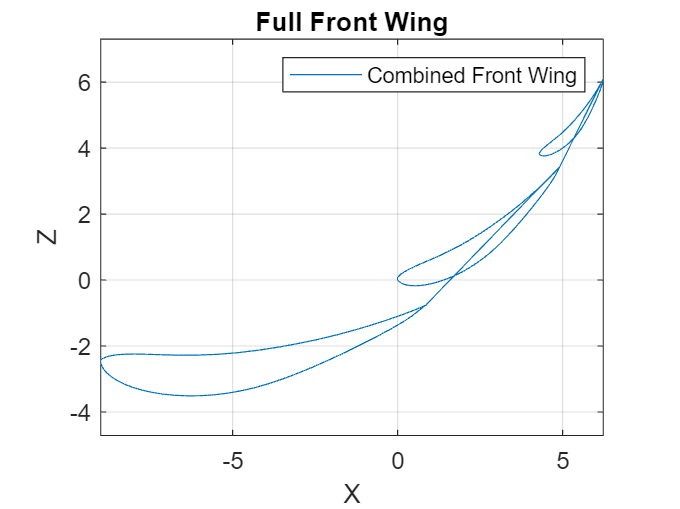

 

% concatenate coordinates
combinedCoordinates = [];
for i=1:airfoilCount
    combinedCoordinates = [combinedCoordinates; wingArray{i}.airfoilCoordinates];
end

% plot
figure;
plot(combinedCoordinates(:, 1), combinedCoordinates(:, 2), '', 'DisplayName', 'Combined Front Wing');
axis equal;
grid on;
xlabel('X');
ylabel('Z');
title('Full Front Wing');
legend('show');


% print length
disp("Chord length of all elements: " + num2str(max(combinedCoordinates(:, 1)) - min(combinedCoordinates(:, 1))));

Chord length of all elements: 15.2284


## Mid Wing

Adjust position in Solidworks as you please, translation doesn't matter in MATLAB

MW = AirfoilModifier( ...
    "Empty.txt", ... % change file input based on airfoil of choice
    "MW.txt", ... % output file name
    0, ... % AOA
    10, ... % scale
    0, ... % x-axis translate
    0, ... % z-axis translate
    true, ... % flip
    true, ... % need Y col
    false, ... % export
    false ); % plot

  